# Seminar Biomedical Engineering and Related Fields

## SW9: Importing and Simulating 4D Cardiac Models for Electrical Impedance Analysis

#### Supervisor: VOSS Daniel

#### Students: COLYBES Elouan & JACQ Mathieu

This document intends to describe the given data, for the Obermeier 2024 paper.

First, we want to plot the volume curve, and its flux curve also:

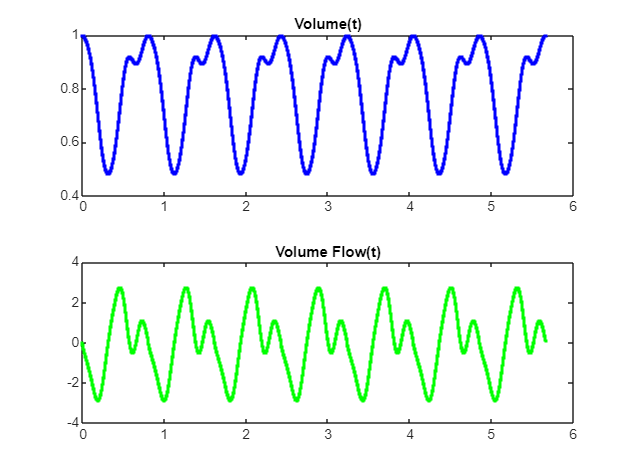

clf; clear;

subject = 3;    % can be 1,2,3

% Import the files
curve = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/VolumeCurve.csv'));
flux = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/VolumeFlux.csv'));


% Preparing plots
tiledlayout(2,1);

% Plotting volume
nexttile;
plot(curve(:,2),curve(:,1),'.',color='blue');
title('Volume(t)');

% Plotting flow
nexttile;
plot(flux(:,2),flux(:,1),'.',color='green');
title('Volume Flow(t)');

We can observe that the volume flow is the first derivative of the volume (it is also by definition).

Then, we wish to observe what the csv scatter plots look like:

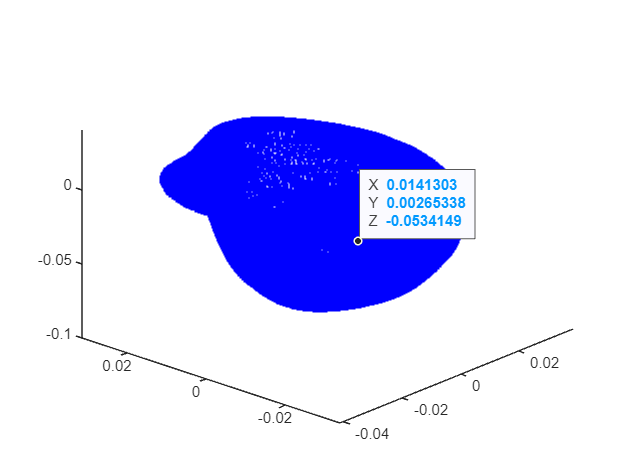

clf; clear;

subject = 3;    % can be 1,2,3
plot = 2;       % can be in 1:10

A = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/GridVelocity_',num2str(plot-1),'.csv'));
% columns of A are X, Y, Z, vx, vy, vz

% Plotting the figure
plot3(A(:,1), A(:,2), A(:,3),'.',color='blue');

Now, we want to be able to generate a video showing the time evolution of the ventricle. For that purpose, we need to map the volume to a spatial position, at each time step. Two solutions are presented here: approximating to the floor known position ; or interpolating between two known solutions.